# Literally copy and paste from matlab:

https://www.mathworks.com/help/fusion/ug/inertial-sensor-noise-analysis-using-allan-variance.html

data = readmatrix('data.csv');
omega = data(2:end, 2);
temp = data(2:end, 3);

t0 = 0.01;

theta = cumsum(omega, 1)*t0;

maxNumM = 100;
L = size(theta, 1);
maxM = 2.^floor(log2(L/2));
m = logspace(log10(1), log10(maxM), maxNumM).';
m = ceil(m); % m must be an integer.
m = unique(m); % Remove duplicates.

tau = m*t0;

avar = zeros(numel(m), 1);
for i = 1:numel(m)
    mi = m(i);
    avar(i,:) = sum( ...
        (theta(1+2*mi:L) - 2*theta(1+mi:L-mi) + theta(1:L-2*mi)).^2, 1);
end
avar = avar ./ (2*tau.^2 .* (L - 2*m));

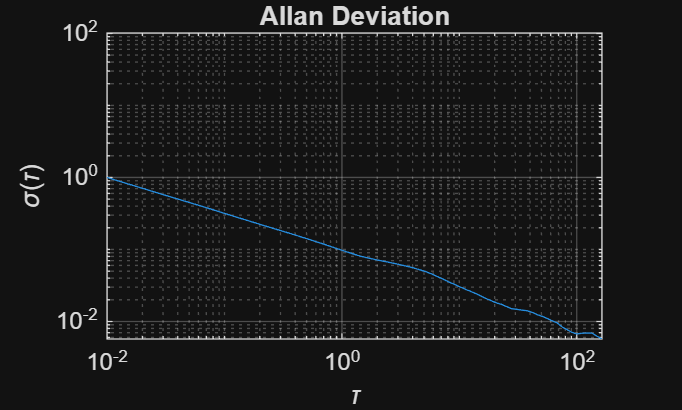

adev = sqrt(avar);

figure
loglog(tau, adev)
title('Allan Deviation')
xlabel('\tau');
ylabel('\sigma(\tau)')
grid on
axis equal

ARW/VRW

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = -0.5;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the angle random walk coefficient from the line.
logN = slope*log(1) + b;
N = 10^logN

N = 0.1008

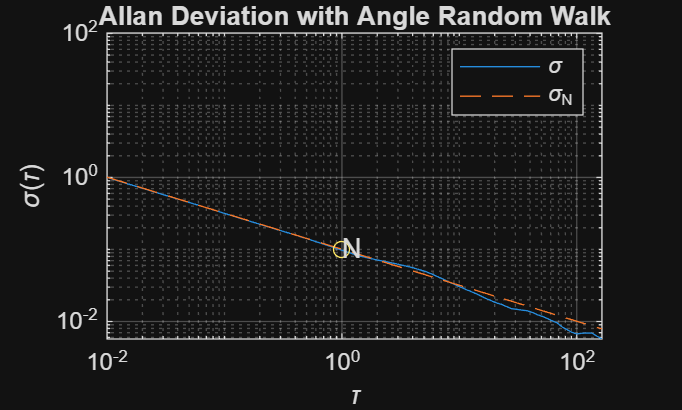


% Plot the results.
tauN = 1;
lineN = N ./ sqrt(tau);
figure
loglog(tau, adev, tau, lineN, '--', tauN, N, 'o')
title('Allan Deviation with Angle Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_N')
text(tauN, N, 'N')
grid on
axis equal

N / sqrt(t0)

ans = 1.0077

Bias Instability

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = 0;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the bias instability coefficient from the line.
scfB = sqrt(2*log(2)/pi);
logB = b - log10(scfB);
B = 10^logB

B = 0.0104

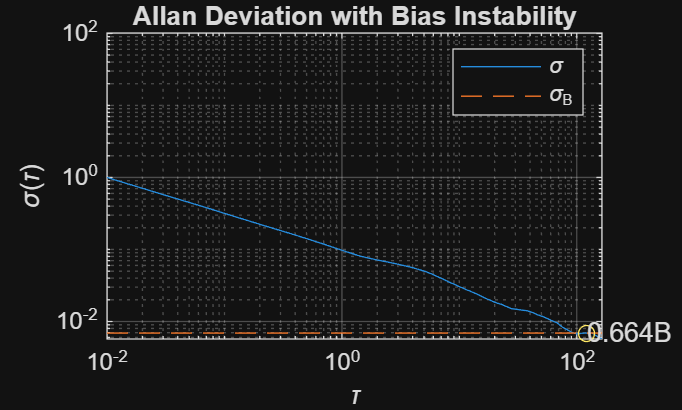


% Plot the results.
tauB = tau(i);
lineB = B * scfB * ones(size(tau));
figure
loglog(tau, adev, tau, lineB, '--', tauB, scfB*B, 'o')
title('Allan Deviation with Bias Instability')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_B')
text(tauB, scfB*B, '0.664B')
grid on
axis equal